# Exercise 3: Idealized sampling

## Ex 3.1

load('DLORENTZ.mat');

fs = 10^6;
[freq_bins, dB_values] = calculateSpectrumdB(DLORENTZ, fs);

figure;
plot(freq_bins, dB_values);

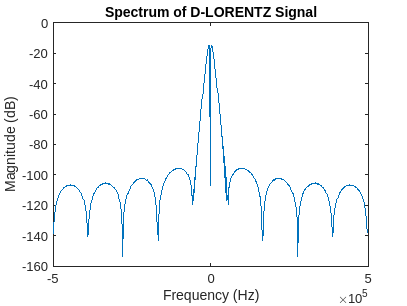

title('Spectrum of D-LORENTZ Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

[frequencies, spectrum_dB] = calculateSpectrumdB(DLORENTZ, fs);

% Define the threshold for significant energy, e.g., -3 dB from the peak
threshold_dB = max(spectrum_dB) - 3;

% Find indices where the spectrum is above the threshold
significant_indices = find(spectrum_dB >= threshold_dB);

% Get the bandwidth
if ~isempty(significant_indices)
    f_low = frequencies(min(significant_indices));
    f_high = frequencies(max(significant_indices));
    bandwidth = f_high - f_low;
else
    bandwidth = 0; % No significant bandwidth found
end

% Display the bandwidth
disp(['The bandwidth of the D_LORENTZ signal is: ', num2str(bandwidth), ' Hz']);

The bandwidth of the D_LORENTZ signal is: 13136.289 Hz


## Ex 3.2

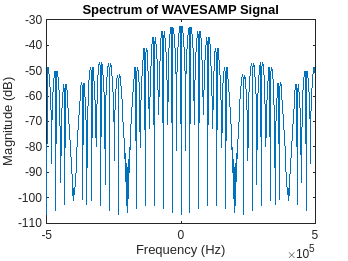

% gating sampling
clear all;
close all;
clc; 

load 'DLORENTZ.mat';
DLORENTZ = DLORENTZ(1:600);
%Do not change any of the values below!
%pulsetrain parameters
n = 10^(-6);                                                       
T_s = 30*n;
tau_1 = (1/6)*T_s;                 
delay1 = (0:30:600)*n;
t_1 = (0:1:600-1)*n;

train1 = pulstran(t_1, delay1, 'rectpuls', tau_1); %the pulsetrain to get WAVE_SAMP
WAVE_SAMP = DLORENTZ'.*train1;

fs = 1/n;
[freq_bins, dB_values] = calculateSpectrumdB(WAVE_SAMP, fs);

figure;
plot(freq_bins, dB_values);
title('Spectrum of WAVESAMP Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

## Ex 3.3

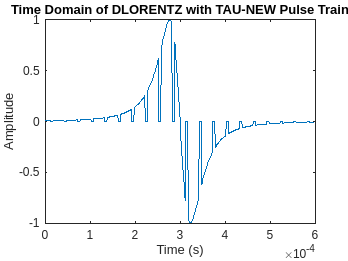

clear all;
close all;
clc; 

load 'DLORENTZ.mat';
DLORENTZ = DLORENTZ(1:600);
% Do not change any of the values below!
% pulsetrain TS_NEW parameters
n = 10^(-6);
T_s3 = 12*n;
tau_3 = (1/6)*T_s3;
delay3 = (0:12:600)*n; % Adjusted forclear all;
close all;
clc; 

load 'DLORENTZ.mat';
DLORENTZ = DLORENTZ(1:600);
%Do not change any of the values below!
%pulsetrain TAU_NEW parameters
n = 10^(-6);
T_s2 = 30*n;
tau_2 = (5/6)*T_s2;
delay2 = (0:30:600)*n;
t_2 = (0:1:600-1)*n;

train2 = pulstran(t_2, delay2, 'rectpuls', tau_2);

%pulsetrain TS_NEW parameters
n = 10^(-6);
T_s3 = 12*n;
tau_3 = (1/6)*T_s3;
delay3 = (0:15:600)*n;
t_3 = (0:1:600-1)*n;

train3 = pulstran(t_3, delay3, 'rectpuls', tau_3);

%space for you to multiply DLORENTZ with the correct pulsetrain and plot
%its time and frequency domain plots

WAVE_TAU_NEW = DLORENTZ'.*train2;

% Plot time domain
figure;
plot(t_3, WAVE_TAU_NEW);
title('Time Domain of DLORENTZ with TAU-NEW Pulse Train');
xlabel('Time (s)');
ylabel('Amplitude');

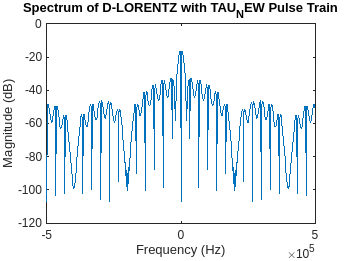


fs = 1/n;
[freq_bins, dB_values] = calculateSpectrumdB(WAVE_TAU_NEW, fs);

% Plot the spectrum
figure;
plot(freq_bins, dB_values);
title('Spectrum of D-LORENTZ with TAU-NEW Pulse Train');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

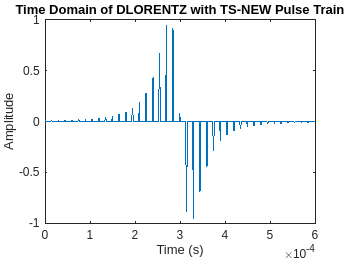



WAVE_TS_NEW = DLORENTZ'.*train3;

% Plot time domain
figure;
plot(t_3, WAVE_TS_NEW);
title('Time Domain of DLORENTZ with TS-NEW Pulse Train');
xlabel('Time (s)');
ylabel('Amplitude');

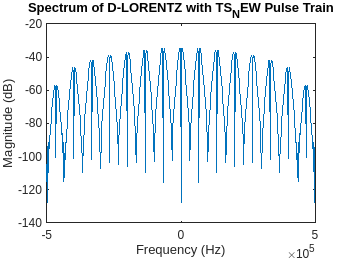


fs = 1/n;
[freq_bins, dB_values] = calculateSpectrumdB(WAVE_TS_NEW, fs);

% Plot the spectrum
figure;
plot(freq_bins, dB_values);
title('Spectrum of D-LORENTZ with TS-NEW Pulse Train');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

- `TAU_NEW`. This means the pulse width is much wider, which could lead to a signal that is less representative of the original signal's variations within each sampling period due to the longer pulse duration.

- `TS_NEW`. This results in a higher sampling frequency and a shorter pulse width, which should capture the signal more accurately by following its variations more closely.

## Ex 3.4

- Gating (natural sampling) can introduce signal distortion due to the varying width and shape of the pulses, potentially affecting the accuracy of signal reconstruction. yields an analog.

## Exercise 4: Quantizing

Plot the flat-top PAM signal.

- (a) The spectrum of a flat-top PAM signal includes the original signal's spectrum modulated by a sinc function, due to the flat-top sampling.

- (b) When τ = Ts, the spectrum experiences less distortion compared to τ < Ts, leading to a broader spectrum with less defined nulls due to the constant pulse width.

Plot the quantized PAM signal.

- (a) To represent 32 levels without redundancy, at least 5 bits are needed (since 2^5=32).

- (b) The SNR increases with increasing levels, as higher resolution allows for more accurate signal representation. But P_e also increases which may lower the signal quality.

- (c) Theoretically, SNR in dB for M levels is given by SNR = 6.02n dB, where n is the number of bits.

- (d) The displayed SNR may not perfectly comply with theory due to quantization error, rounding, or noise in the simulation.

Now, the signal needs to go through an encoder. Plot the PCM signal.

- (a) The pre-set bit rate R depends on the app settings and does not inherently change with increasing levels; it's determined by the sampling rate and the number of bits per sample. which relates to levels.

- (b) The required bandwidth for the PCM signal, *B**PCM*, is determined by the Nyquist rate, which is half the sampling rate for a baseband signal. Here we have unipolar which means B_PCM = 1.

- (c) To achieve T_b=0.0001 s, choose R such that R=1/T_b, meaning *R*=10,000 bps.

- (d) If *T**b*=0.0001 s for a 32-level signal, 5 bits and a sumbol is basically a word of bits so 5 * 0.0001 = 0.0005 = Ts